clear
data = readtable('cam_torque_data.csv', 'VariableNamingRule','preserve');
all_time = data.time;
all_angle = data.angle;
all_torque = data.torque;

% angleChange = diff(all_angle);
% directionChange = find(angleChange(1:end-1) .* angleChange(2:end) <= 0);
% 
% % Add start and end indices
% directionChange = [1; directionChange; length(all_angle)];
% 
% % Initialize arrays to store upper and lower curve data
% upperAngle = [];
% upperTorque = [];
% lowerAngle = [];
% lowerTorque = [];
% 
% % Separate curves based on direction change
% for i = 1:length(directionChange)-1
%     startIdx = directionChange(i);
%     endIdx = directionChange(i+1);
% 
%     if mean(all_torque(startIdx:endIdx)) > 0
%         upperAngle = [upperAngle; all_angle(startIdx:endIdx)];
%         upperTorque = [upperTorque; all_torque(startIdx:endIdx)];
%     else
%         lowerAngle = [lowerAngle; all_angle(startIdx:endIdx)];
%         lowerTorque = [lowerTorque; all_torque(startIdx:endIdx)];
%     end
% end
% 
% figure;
% subplot(1, 2, 1);
% plot(upperAngle, upperTorque, 'LineWidth', 2);
% xlabel('Angle (deg)');
% ylabel('Torque (Nm)');
% title('Upper Curve');
% grid on;
% subplot(1, 2, 2);
% plot(lowerAngle, lowerTorque, 'LineWidth', 2);
% xlabel('Angle (deg)');
% ylabel('Torque (Nm)');
% title('Lower Curve');
% grid on;

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    4.716301e+05     0.000e+00     1.000e+00     0.000e+00     4.485e+07  
    1          73    3.966798e+05     3.036e-18     1.481e-09     4.087e-02     3.928e+07  
    2         114    3.704477e+05     5.054e-05     7.731e-06     1.379e+00     3.880e+07  
    3         150    3.416543e+05     2.252e-05     4.600e-05     2.162e+00     3.881e+07  
    4         196    3.311958e+05     2.819e-04     1.299e-06     4.997e+00     3.883e+07  
    5         208    2.866705e+05     2.113e+00     2.401e-01     6.699e+00     2.918e+07  
    6         220    2.676378e+05     2.325e+00     2.401e-01     7.750e+00     3.375e+07  
    7         231    1.786333e+05     2.087e+00     3.430e-01     8.062e+00     2.183e+07  
    8         245    1.443395e+05     1.971e+00     1.176e-01     3.563e+00     2.

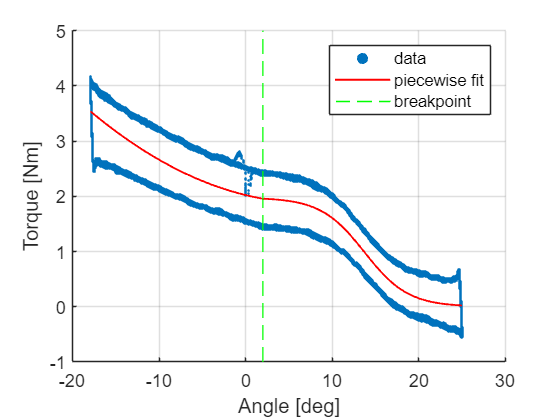

piecewise_fit(all_angle, all_torque);

function piecewise_fit(all_angle, all_torque)
    initial_params = [0, 0, median(all_angle), 0, 0, 0, median(all_angle)];
    lower_bound = [-Inf, -Inf, min(all_angle), -Inf, -Inf, -Inf, -20];
    upper_bound = [Inf, Inf, max(all_angle), Inf, Inf, Inf, 10];
    options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
    
    [best_params, fval] = fmincon(@(params) objective(params, all_angle, all_torque),...
                                    initial_params,...
                                    [], [], [], [],...
                                    lower_bound, upper_bound,...
                                    @(params) continuity_constraint(params, all_angle, all_torque),...
                                    options);
    print_piecewise_functions(best_params)
    % Predicted Function
    y_pred = arrayfun(@(x) piecewise_eval(x, best_params), all_angle);
    
    % Fit Quality
    SST = sum((all_torque - mean(all_torque)).^2);
    SSR = sum((all_torque - y_pred).^2);
    R_squared = 1 - (SSR / SST);
    RMSE = sqrt(mean((all_torque - y_pred).^2));
    disp(['Fit Quality: R2 = ' num2str(R_squared) ', RMSE = ' num2str(RMSE)]);
    
    % Plot
    figure%('Position', [100, 100, 960, 720]);
    scatter(all_angle, all_torque, 2, 'filled');
    hold on
    % Fit Curve
    plot(all_angle, y_pred, 'r-', 'LineWidth', 1);
    hold on
    % Upper Curve
    % plot(all_angle, y_pred+0.5, 'LineWidth', 2);
    % hold on
    % % Lower Curve
    % plot(all_angle, y_pred-0.5, 'LineWidth', 2);
    % hold on
    % Breakpoint
    line([best_params(7) best_params(7)], ylim, 'Color', 'green', 'LineStyle', '--');
    
    grid on
    xlabel('Angle [deg]');
    ylabel('Torque [Nm]');
    legend('data', 'piecewise fit', 'breakpoint');
    hold off;
end

function ssr = objective(params, all_angle, all_torque)
    L = params(1);
    k = params(2);
    x0 = params(3);
    a = params(4);
    b = params(5);
    c = params(6);
    breakpoint = params(7);
    
    logistic_y = L ./ (1 + exp(-k .* (all_angle(all_angle > breakpoint) - x0)));
    polynomial_y = a * all_angle(all_angle <= breakpoint).^2 + b * all_angle(all_angle <= breakpoint) + c;   
    ssr = sum((all_torque(all_angle > breakpoint) - logistic_y).^2) + sum((all_torque(all_angle <= breakpoint) - polynomial_y).^2);
end

function [c, ceq] = continuity_constraint(params, all_angle, all_torque)
    L = params(1);
    k = params(2);
    x0 = params(3);
    a = params(4);
    b = params(5);
    c = params(6);
    breakpoint = params(7);
    
    logistic_at_breakpoint = L / (1 + exp(-k * (breakpoint - x0)));
    polynomial_at_breakpoint = a * breakpoint^2 + b * breakpoint + c;
    
    ceq = logistic_at_breakpoint - polynomial_at_breakpoint;
    
    c = [];
end

function y = piecewise_eval(x, params)
    L = params(1);
    k = params(2);
    x0 = params(3);
    a = params(4);
    b = params(5);
    c = params(6);
    breakpoint = params(7);

    if x > breakpoint
        y = L ./ (1 + exp(-k .* (x - x0)));
    else
        y = a .* x.^2 + b .* x + c;
    end
end

function print_piecewise_functions(params)
    L = params(1);
    k = params(2);
    x0 = params(3);
    a = params(4);
    b = params(5);
    c = params(6);
    breakpoint = params(7);

    % Create strings representing the logistic and polynomial equations
    logistic_eq = ['y = ' num2str(L) ' / (1 + exp(-' num2str(k) ' * (x - ' num2str(x0) ')))'];
    poly_eq = ['y = ' num2str(a) ' * x^2 + ' num2str(b) ' * x + ' num2str(c)];

    % Display the piecewise function equations
    disp(logistic_eq);
    disp(poly_eq);
    disp(['Breeakpoint =' num2str(breakpoint)]);

    fitParams = struct;
    fitParams.L = L;
    fitParams.k = k;
    fitParams.x0 = x0;
    fitParams.a = a;
    fitParams.b = b;
    fitParams.c = c;
    fitParams.breakpoint = breakpoint;
    jsonString = jsonencode(fitParams);

    filename = 'piecewise_fit_params.json';
    fid = fopen(filename, 'w');
    if fid == -1
        error('Cannot create JSON file.');
    end
    fwrite(fid, jsonString, 'char');
    fclose(fid);
    disp(['Piecewise fit parameters written to ', filename]);
end